# DIntroduction à Simulink : commande du circuit RC

Dans ce document livescript, vous allez découvrir comment utiliser la bibliothèque Simulink de MATLAB pour réaliser la commande d'un circuit RC. Cet exemple reprend le système du premier  ordre traîté dans l'exercice 1. Il vous permettra de bien faire la distinction entre MATLAB et Simulink et de voir les liens existants entre les deux.

## Découverte de l'interface Simulink

Commençez par cliquer sur le bouton "Home" présent dans le ruban en haut à gauche de votre écran.

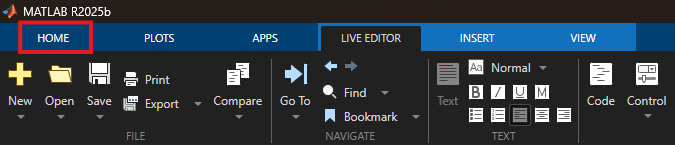

Ensuite cliquez sur l'icône "Simulink" présente en haut de votre écran.

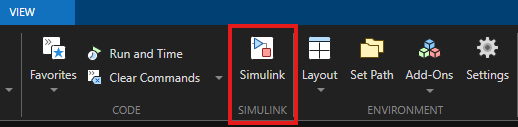

Une fenêtre s'ouvre. Cliquez ensuite sur "Blank Model".

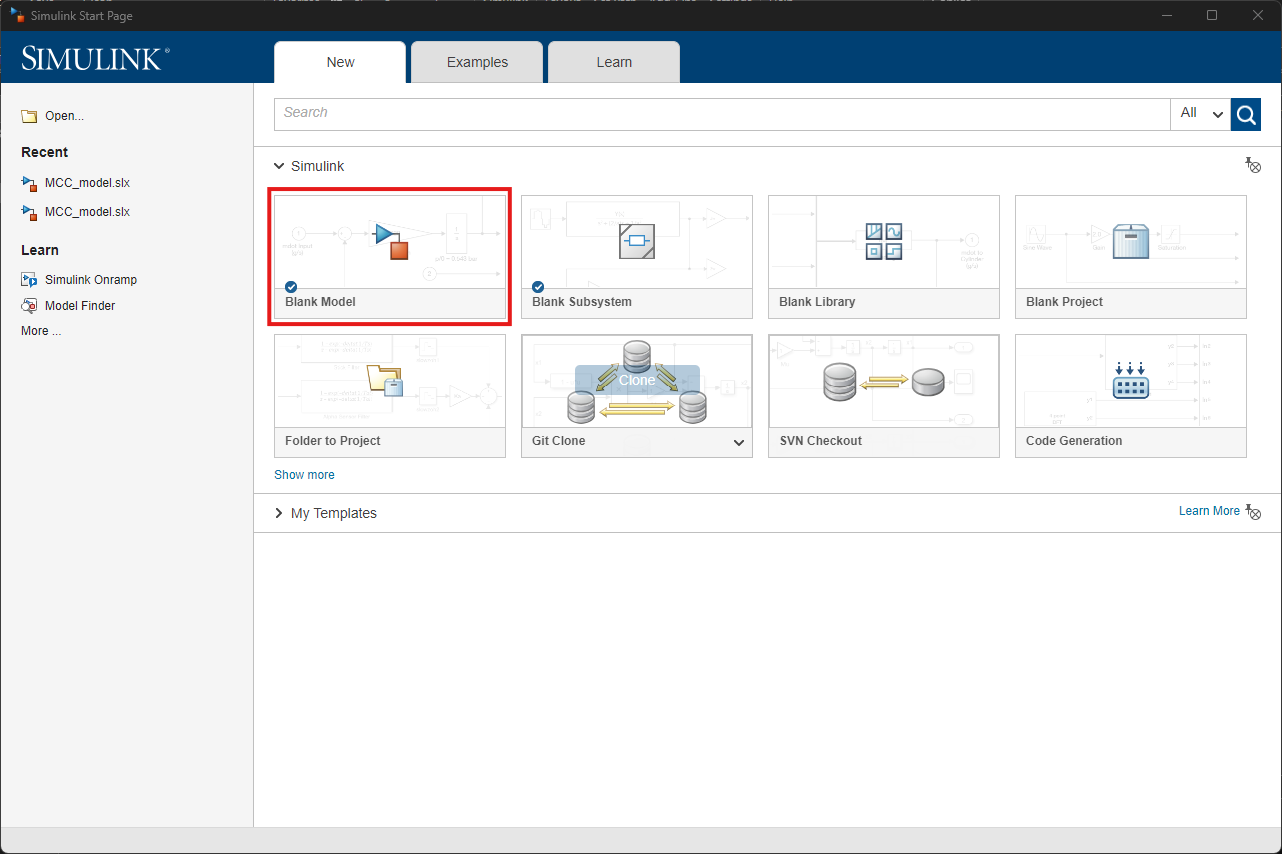

Vous obtenez la fenêtre suivante. Cliquez sur le bouton "Save" en haut à gauche et enregistrez le fichier avec le nom "Exercice2_Simulink".

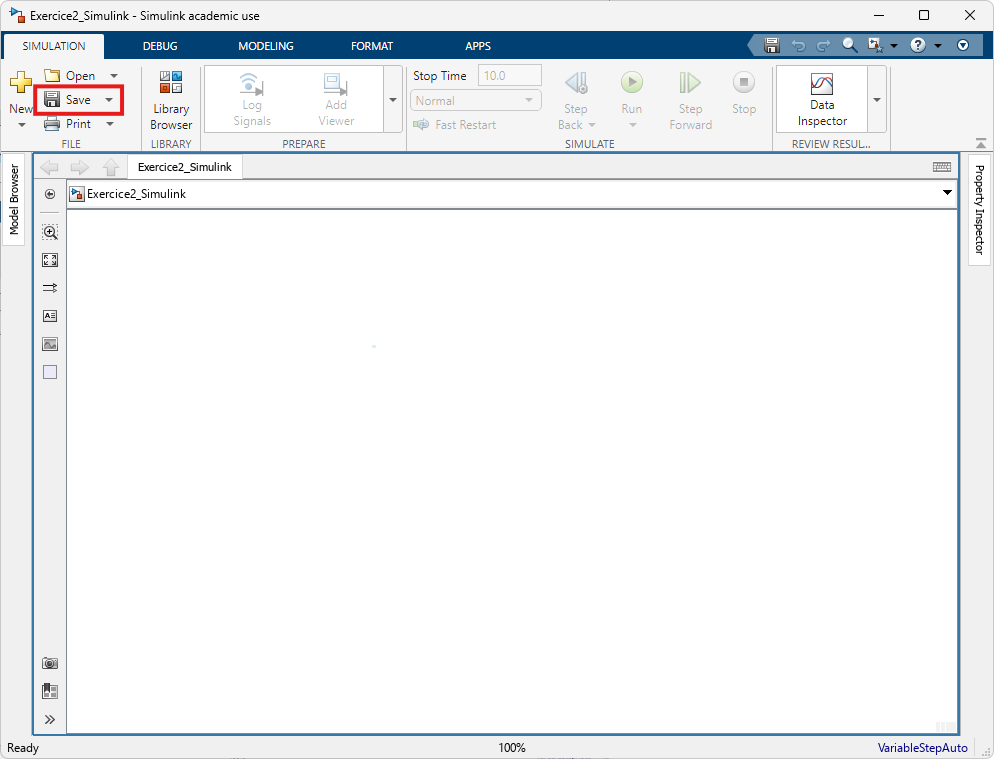

Vous êtes maintenant prêts à utiliser Simulink.

## Commande d'un circuit RC

Dans cet exercice, vous allez étudier le comportement d'un système du premier ordre (circuit RC) en boucle ouverte dans un premier temps. Ensuite vous implémenterez un correcteur proportionnel (P) et étudierons le comportement du système en boucle fermée.

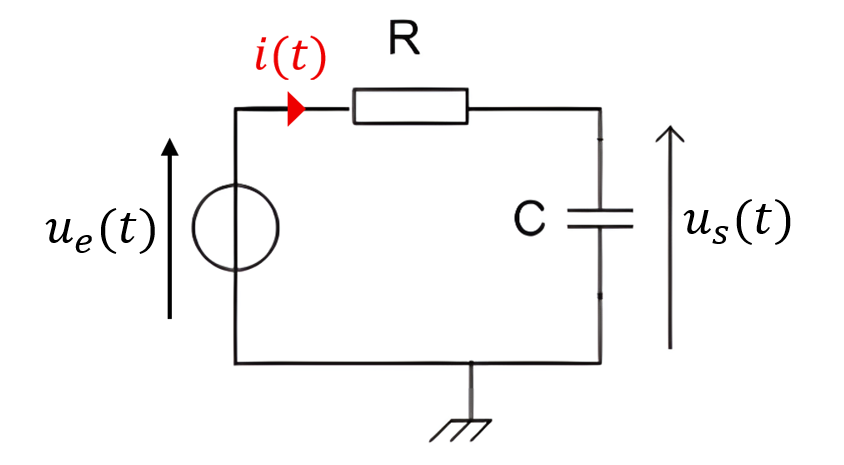

Pour déterminer l'équation différentielle du système, on utilise la loi des mailles : $u_e \left(t\right)=R\ldotp i\left(t\right)+u_s \left(t\right)$.

On rappelle que $i\left(t\right)=C\ldotp \dot{u_s } \left(t\right)$ avec $\dot{u_s } \left(t\right)=\frac{\mathrm{d}}{\mathrm{d}t}u_s \left(t\right)$, donc en remplaçant $i\left(t\right)$ dans la loi des mailles on obtient $e\left(t\right)=R\ldotp C\ldotp \dot{u_s } \left(t\right)+u_s \left(t\right)$.

Simulink permet de résoudre des équations sous forme de schéma bloc exprimées dans le domaine de Laplace. vous allez donc appliquer la transformée de Laplace à l'équation différentielle du circuit RC : $U_e \left(p\right)=\textrm{RC}\ldotp U_s \left(p\right)\ldotp p+U_s \left(p\right)\Rightarrow U_e \left(p\right)=U_s \left(p\right)\ldotp \left(1+\textrm{RC}\ldotp p\right)$

On en déduit la fonction de transfert du système $H\left(p\right)=\frac{U_s \left(p\right)}{U_e \left(p\right)}\Rightarrow H\left(p\right)=\frac{1}{1+\textrm{RC}\ldotp p}$.

### Commande du système en boucle ouverte

Dans un premier temps, vous allez observer la réponse du circuit RC à un échelon unitaire.

Il faut commencer par définir les valeurs numériques de $R$ et $C$ **dans MATLAB. **$R=100\;k\Omega$ et $C=5\;\mu F$ :

clear; % efface toutes les variables présentes dans le workspace qui ont pu être créées par d'autres programmes
R = 1e5;
C = 5e-6;

Cliquez sur le bouton "Run" pour charger les variables $R$ et $C$ dans le workspace.

Ensuite ouvrez la fenêtre Simulink et ajoutez ces 3 blocs :

- un bloc "Transfer Fcn" pour modéliser le système par sa focntion de transfert

- un bloc "Step" pour créer un échelon d'entrée

- un bloc "Scope" pour voir la courbe du signal de sortie

Pour ajouter un bloc, cliquez sur l'icône "Library Browser". Ensuite cherchez dans "Commonly Used Blocks", "Continuous" ou "Sources" pur trouver les blocs dont vous avez besoin.

 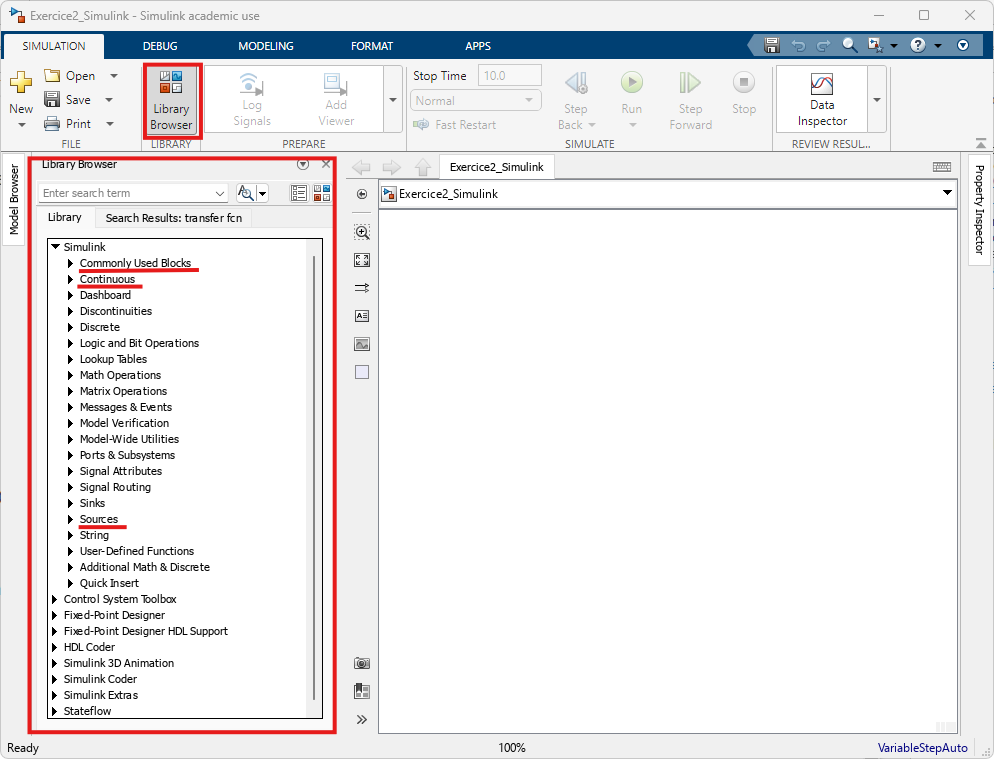 +

Ensuite, faites glisser votre bloc dans l'espace de travail Simulink.

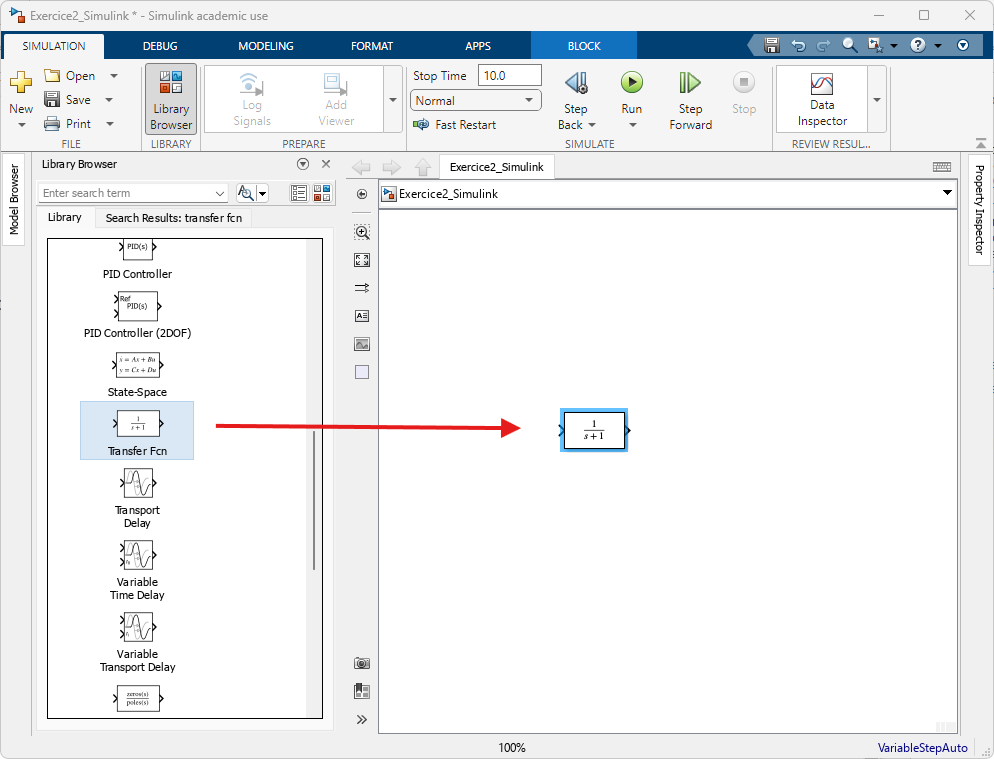

Astuce : vous pouvez égalment double-cliquer sur l'espace blanc dans votre fichier Simulink pour faire apparaître une barre de recherche vous permettant d'accéder aux blocs souhaités plus rapidement.

Répétez l'opération pour les blocs "Step" et "Scope".

Vous devriez obtenir trois blocs comme sur l'image ci-dessous :

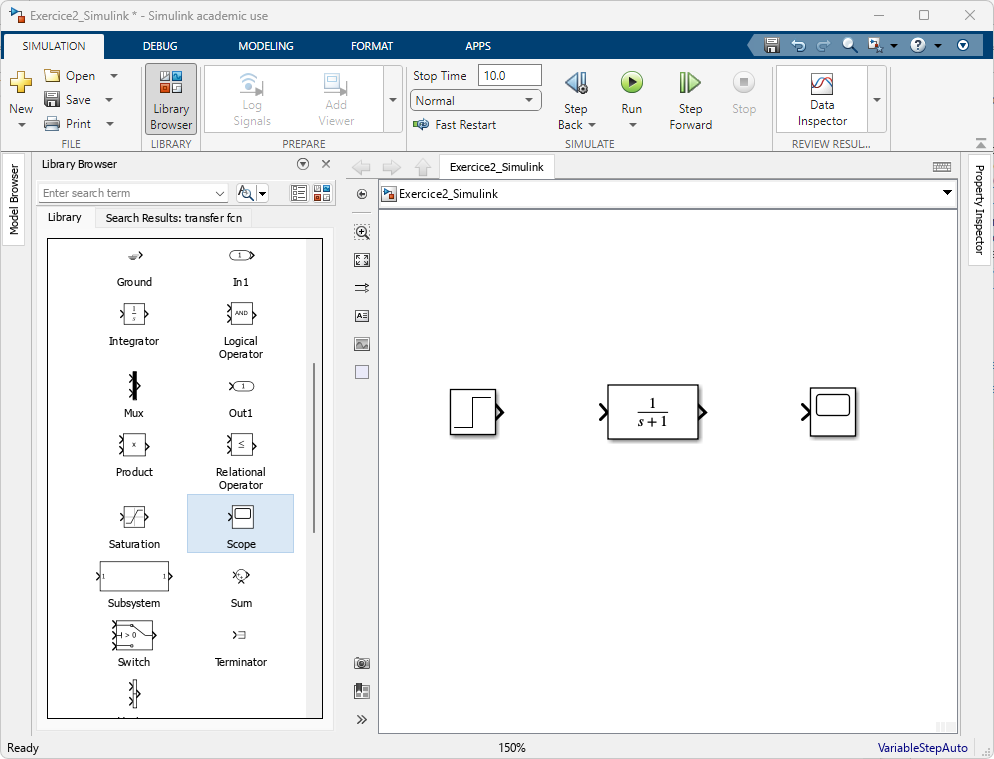

Tracez des flèches entre les 3 blocs.

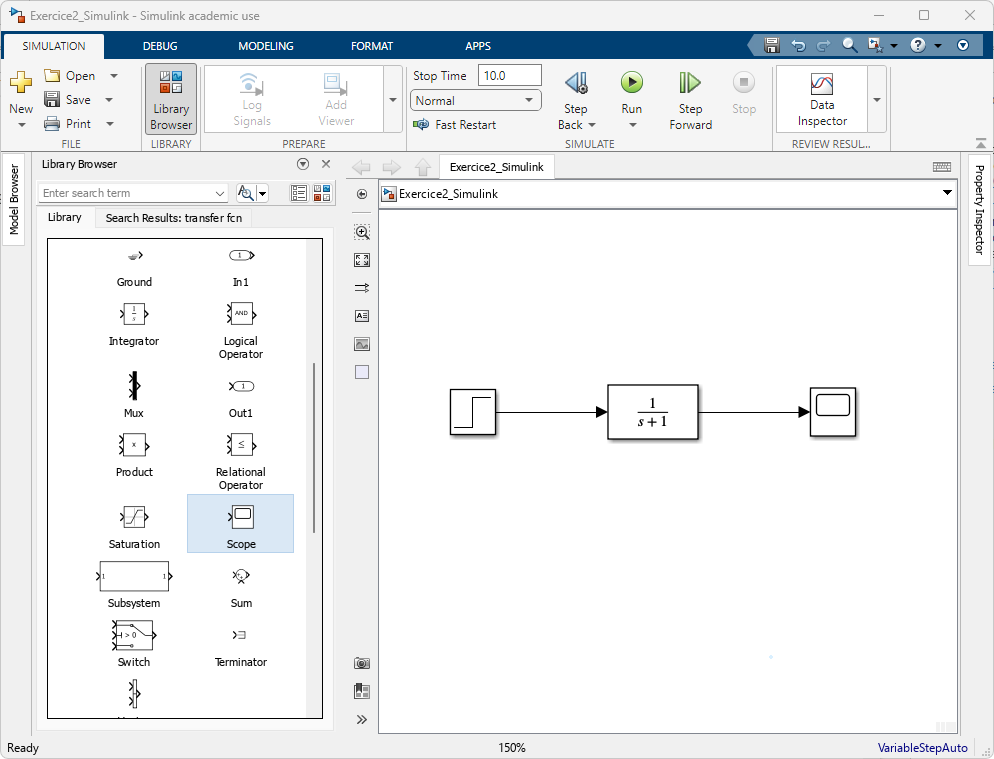

Maintenant, vous allez paramétrer les blocs.

Double-cliquez sur le bloc "Step", cette fenêtre va s'ouvrir :

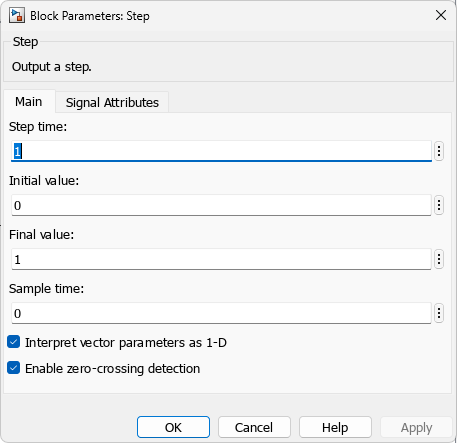

Mettez le "Step time" à 0 pour que l'échelon démarre à $t=0$s. Validez en appuyant sur "OK".

Ensuite, double-cliquez sur le bloc "Transfer Fcn", cette fenêtre va s'ouvrir :

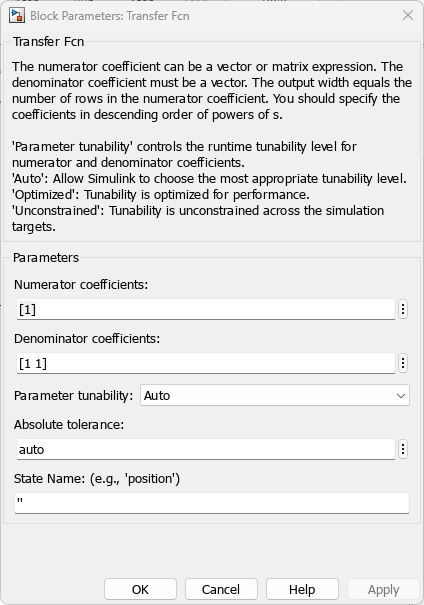

On rappelle que la fonction de transfert du système est $H\left(p\right)=\frac{1}{1+\textrm{RC}\ldotp p}$. Remplacez [1 1] dans la section "Denominator coefficients" par [R*C 1] pour définir la fonction de transfert. $R$ et $C$ seront bien définis dans Simulink si les valeurs sont dans le workspace grace à l'execution du code que vous avez écrit précédemment.

Maintenant réglez le temps de simulation sur 4s en modifiant la valeur dans la case "Stop time".

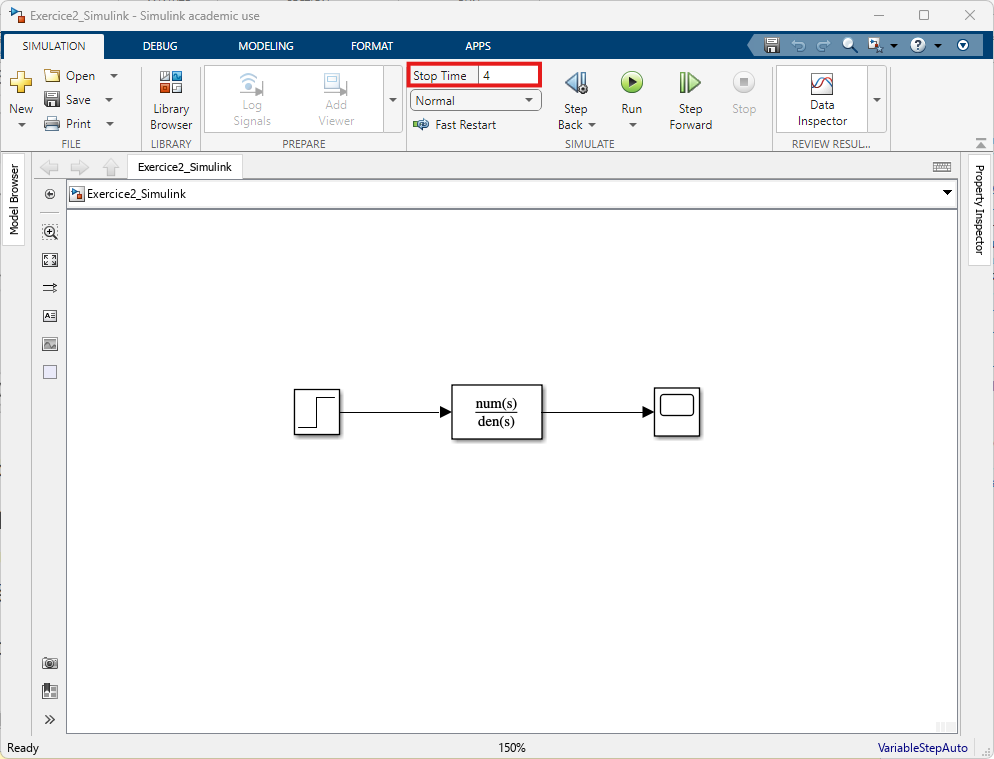

Maintenant, lancez la simulation en appuyant sur le bouton "Run" en haut à gauche.

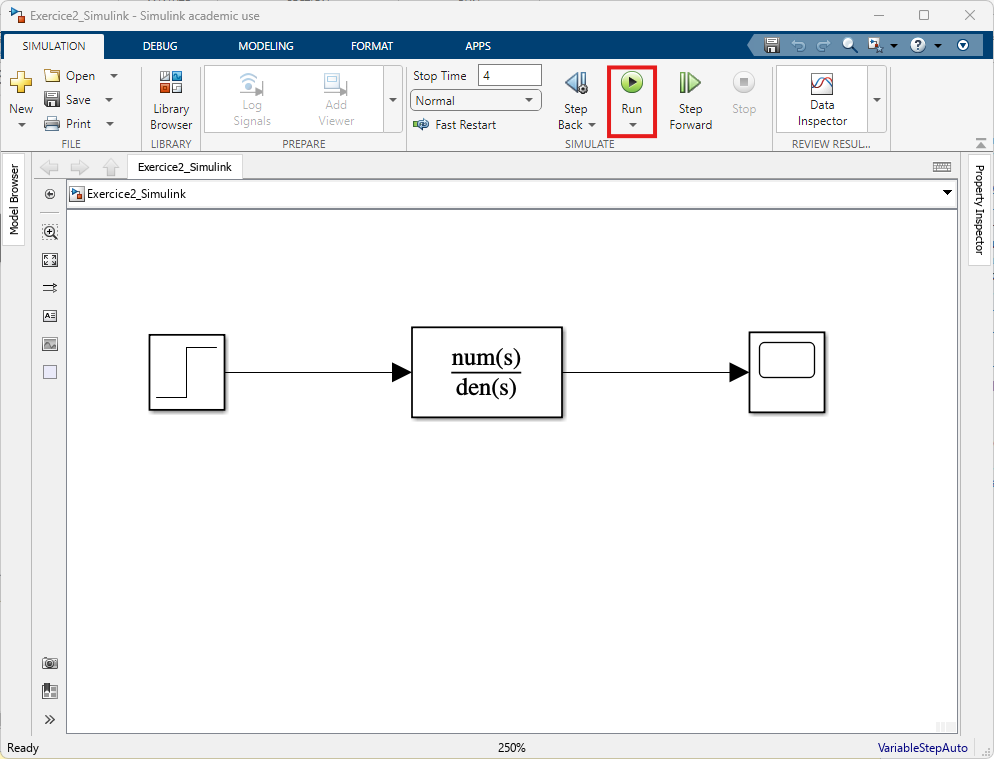

Double-cliquez sur le bloc "Scope" pour voir a réponse à un échelon du système.

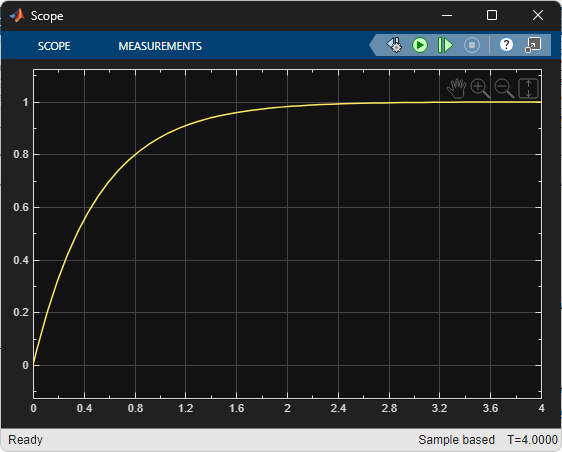

On obtient le même graphique que dans l'exercice 1.

Changeons maintenant l'entrée en rampe. C'est là qu'est l'avantage de Simulink, il suffit de remplacer le bloc "Step" par un bloc "Ramp".

Voici la réponse du système que l'on obtient.

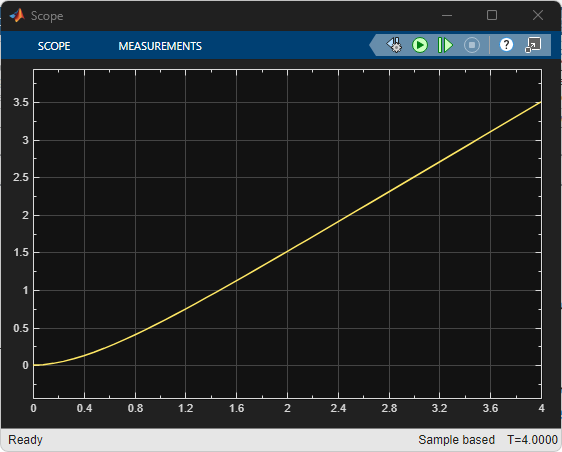

Sur cette courbe, difficile de savoir si la consigne est bien suivie ou non vu qu'elle n'apparaît pas sur la figure. Pour l'ajouter à la figure, on peut ajouter un bloc "Mux".

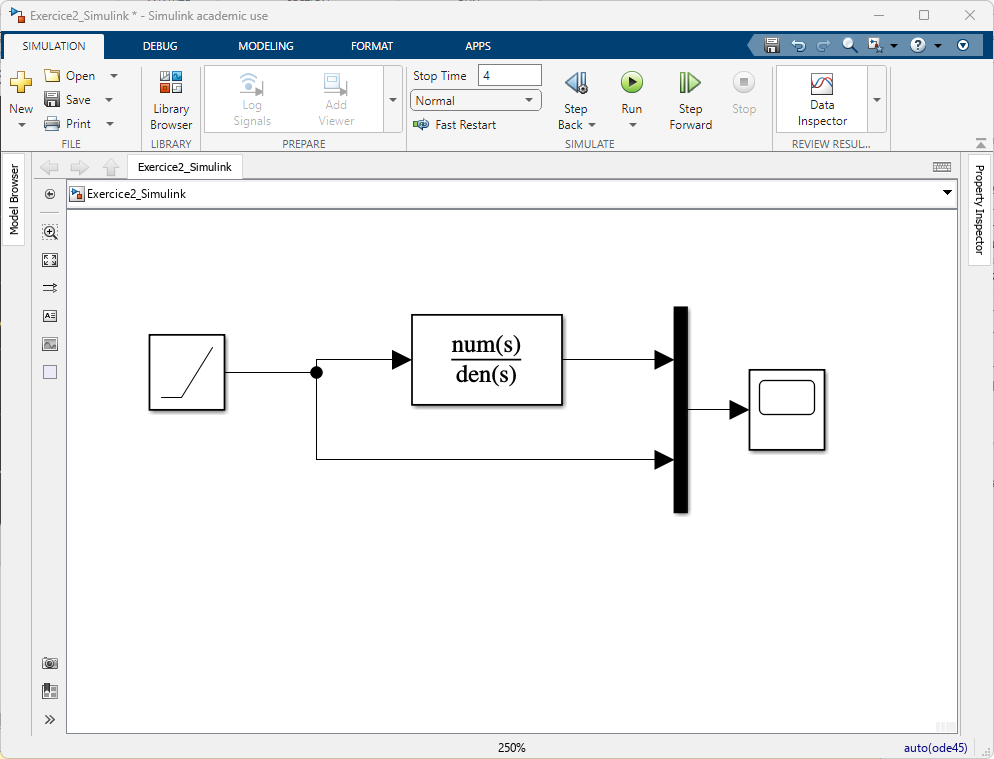

Voici la nouvelle figure que l'on obitent après avoir relancé la simulatio et ouvert le "Scope".

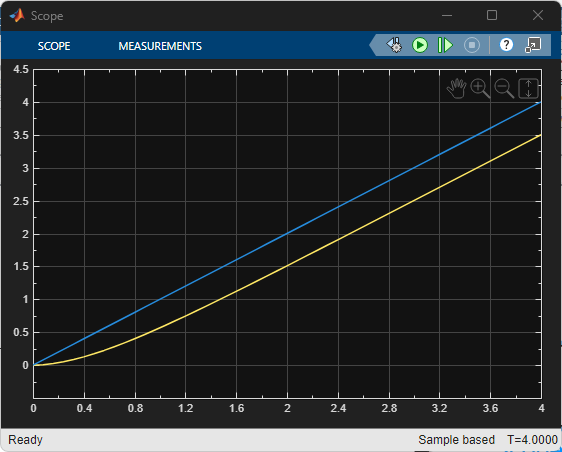

On voit qu'une erreur de trainage est présente en boucle ouverte.

### Commande en boucle fermée : implémentation d'un correcteur proportionnel

Maintenant, vous allez implémenter un correcteur proportionnel pour tener d'améliorer les performances du système. On considère a nouveau que l'entrée est un échelon qui démarre à $t=0$s.

On rappelle le schéma de la fonction de transfert en boucle fermée du circuit RC.

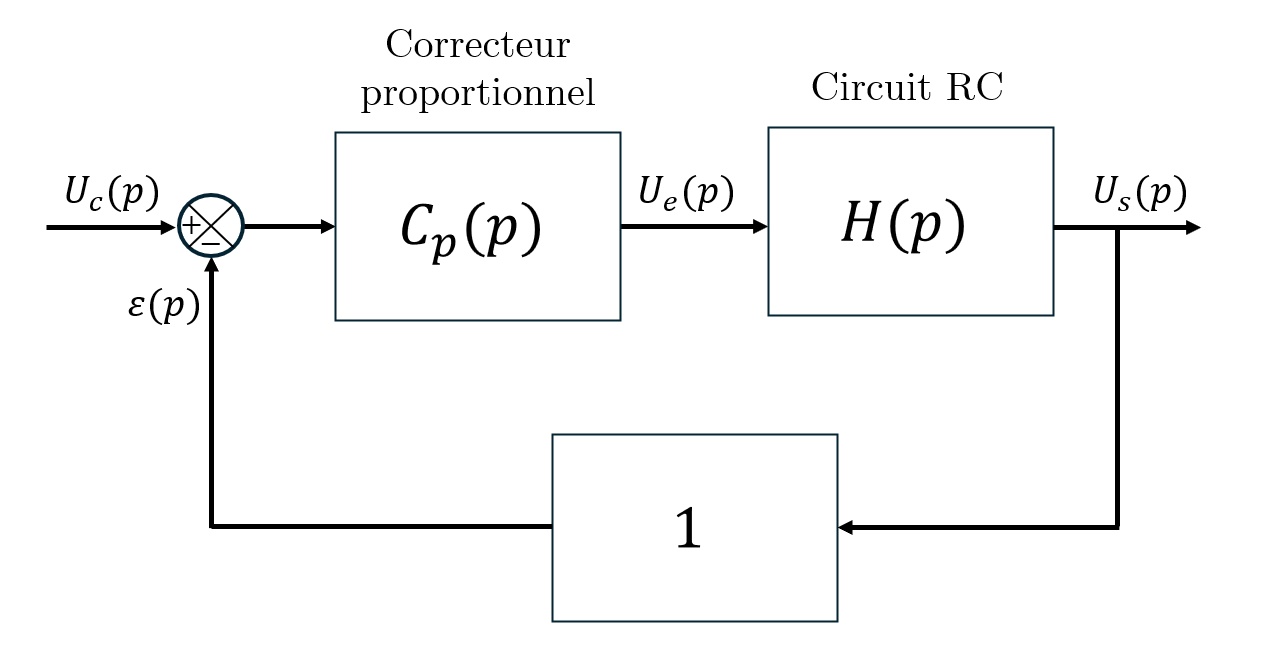

La fonction de transfert du correcteur est $C_p \left(p\right)=K_{p\;}$.

Pour écrire la fonction de transfert du correcteur on peut utiliser un bloc "Gain" au lieu d'un bloc "Transfer Fcn". Le bloc sommateur qui permet de calculer l'erreur s'appelle "Sum".

Prenons $K_p =50$, reproduisez ce schéma sur Simulink.

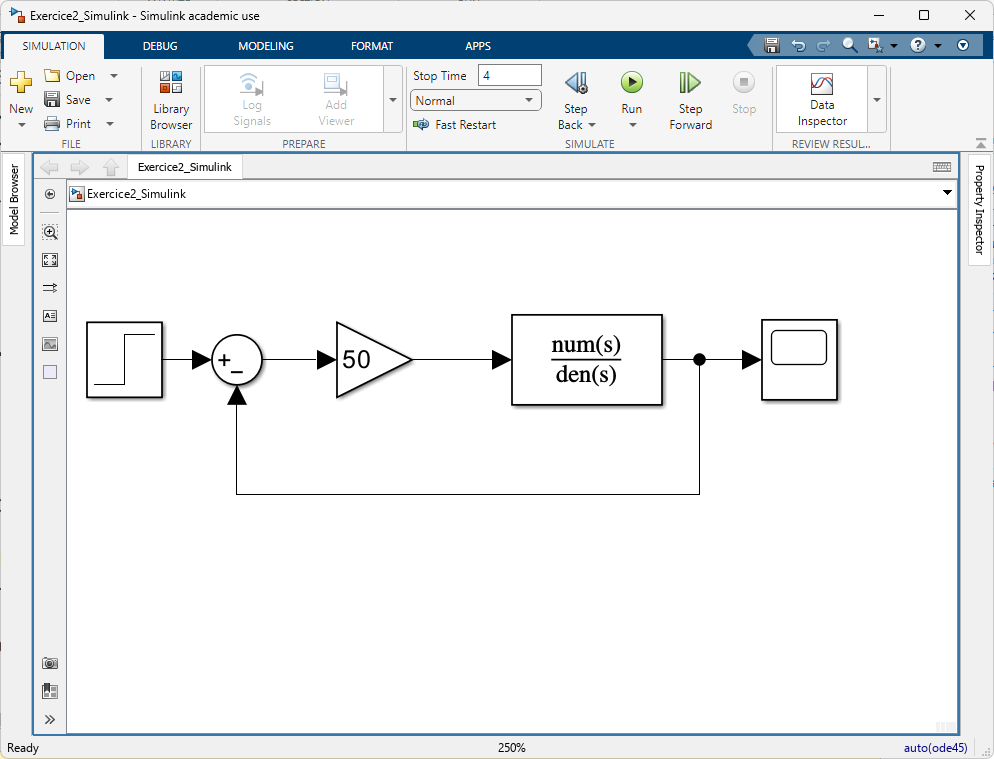

Tracez la réponse du système en boucle fermée. Vous devez obtenir le graphe suivant :

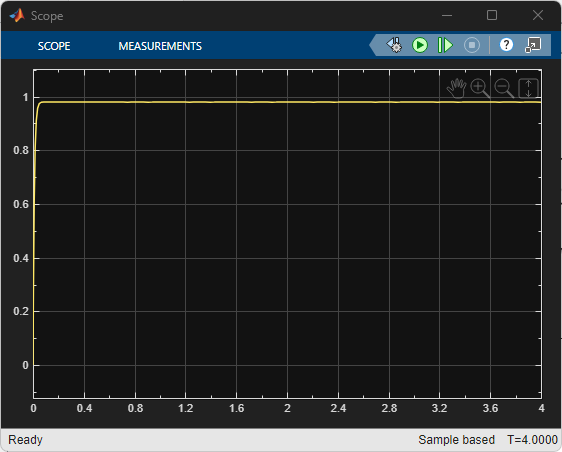

On retrouve bien la courbe que l'on avait obtenu dans l'exercice 1.